# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 이강희**

**학번**** : 201710956**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

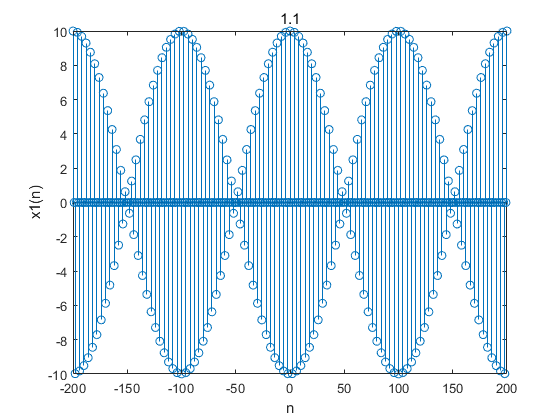

n = [-200:200];
x1 = 5 * (cos(0.49*pi*n) + cos(0.51*pi*n));

figure;
stem(n,x1);
title('1.1'); xlabel('n'); ylabel('x1(n)');

2) 

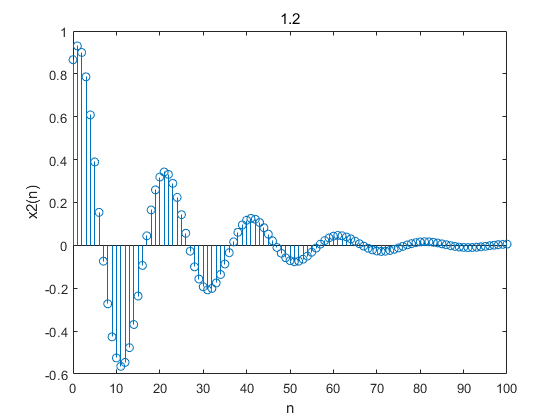

n = [0:100];
x2 = exp(-0.05*n) .* sin(0.1*pi*n + pi/3);

figure;
stem(n,x2);
title('1.2'); xlabel('n'); ylabel('x2(n)');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

b = [1, 2, 0, 1];
a = [1, 0.50, 0.25];
n = [0:100];
h = impz(b,a,n);

subplot(2,1,1);
stem(n,h);
title('2.1'); xlabel('n'); ylabel('Impulse response');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))   % 값이 5.2857로 absolutely summarble 하므로 BIBO 안정합니다.

ans = 5.2857

3) 만약 이 시스템의 입력이  x = 5 + 3*cos(0.2*pi*n) + 4*sin(0.6*pi*n)이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

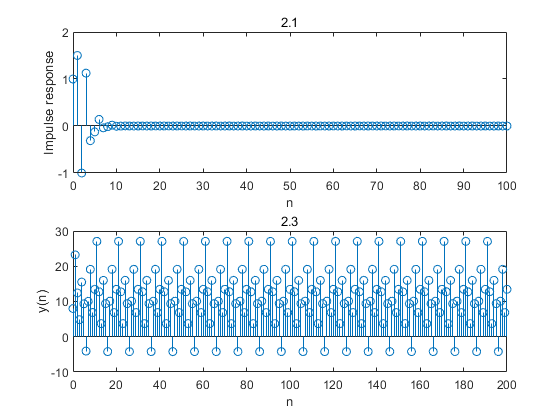

n = [0:200];
x = 5 + 3*cos(0.2*pi*n) + 4*sin(0.6*pi*n);
y = filter(b,a,x);

subplot(2,1,2);
stem(n,y);
title('2.3'); xlabel('n'); ylabel('y(n)');

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

n = [0:50];
Y1 = zeros(1,length(n));
for k = 0:50
    Y1 = Y1 + ((0.8).^k .* (-0.9).^(n-k));
end

subplot(3,1,1);
stem(Y1);
title('3.1'); xlabel('n'); ylabel('y(n)');

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

n = [0:25];
x = 0.8.^n;
h = (-0.9).^n;
Y2 = conv(h,x);

subplot(3,1,2);
stem(Y2);
title('3.2'); xlabel('n'); ylabel('y(n)');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

n = [0:50];
h = (-0.9).^n;
b = exp(j*w);
a = exp(j*w) - 0.8;
Y3 = filter(b,a,h);

subplot(3,1,3);
stem(Y3);

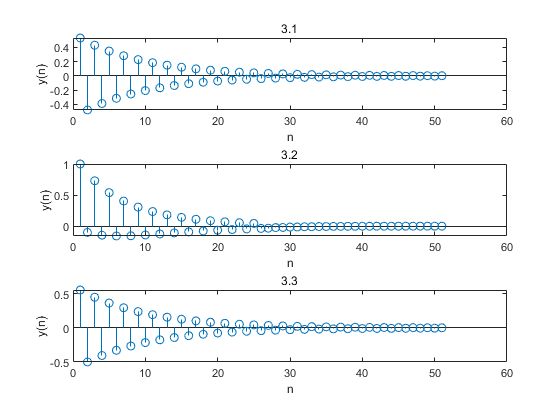

title('3.3'); xlabel('n'); ylabel('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

k = [-200:200];
w = pi*k/200;
X1 = exp(j*w) ./ (exp(j*w) - 0.9*ones(1,401));
X2 = exp(j*w) ./ (exp(j*w) + 0.9*ones(1,401));
H1 = X1 + X2;
magH1 = abs(H1); angH1 = angle(H1);

subplot(2,2,1);
plot(w/pi,magH1);
title('4.1 magH1'); xlabel('frequency in pi units'); ylabel('|H|');
subplot(2,2,2);
plot(w/pi,angH1);
title('4.1 angH1'); xlabel('angle in pi units'); ylabel('phase in pi radians');

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

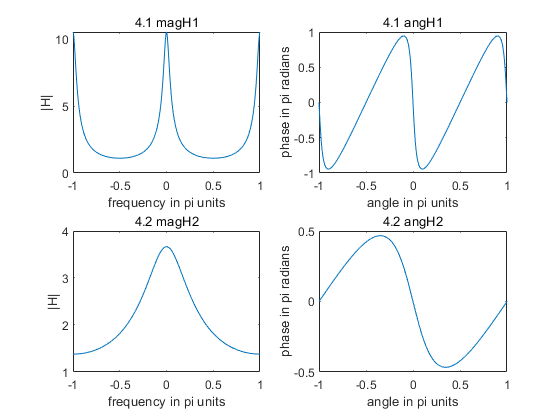

k = [-200:200];
w = pi*k/200;
X1 = exp(j*w) ./ (exp(j*w) - 0.5*ones(1,401));
X2 = exp(j*w) ./ (exp(j*w) - 0.4*ones(1,401));
H2 = X1 + X2;
magH2 = abs(H2); angH2 = angle(H2);

subplot(2,2,3);
plot(w/pi,magH2);
title('4.2 magH2'); xlabel('frequency in pi units'); ylabel('|H|');
subplot(2,2,4);
plot(w/pi,angH2);
title('4.2 angH2'); xlabel('angle in pi units'); ylabel('phase in pi radians');

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

b = [1 0 1];
a = [1 0.95 0.9025];

[H3] = freqresp(b,a,w);
magH3 = abs(H3); angH3 = angle(H3);

subplot(2,2,1);
plot(w/pi,magH3);
title('6.1 magH3'); xlabel('frequency in pi units'); ylabel('|H|');
subplot(2,2,2);
plot(w/pi,angH3);
title('6.1 angH3'); xlabel('angle in pi units'); ylabel('phase in pi radians');

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

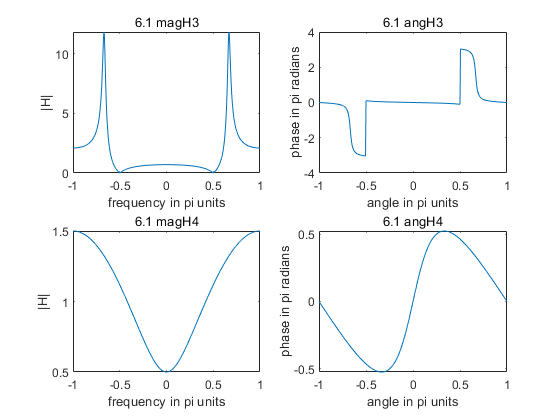

l = [1:5];
b = [1];
a = 0.5.^n;
[H4] = freqresp(b,a,w);
magH4 = abs(H4); angH4 = angle(H4);

subplot(2,2,3);
plot(w/pi,magH4);
title('6.1 magH4'); xlabel('frequency in pi units'); ylabel('|H|');
subplot(2,2,4);
plot(w/pi,angH4);
title('6.1 angH4'); xlabel('angle in pi units'); ylabel('phase in pi radians');

5. (P3.17) 

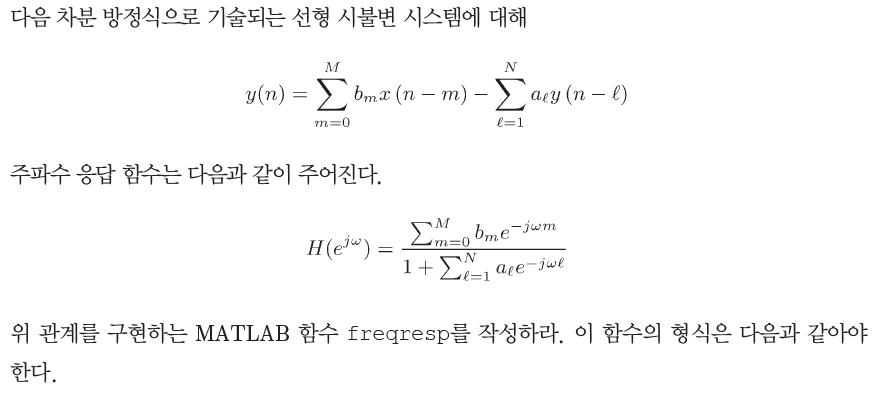

function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array

m = 0:length(b)-1;
l = 0:length(a)-1;
k = [-200:200];
w = pi*k/200;

num = b*exp(-j*m'*w);
den = a*exp(-j*l'*w);
H = num ./ den;

end